# Метод инвариантного погружения

### Школьная задачка


$$\sqrt{3+\sqrt{3+ \sqrt{3...}}} -?$$



$$F(n) = \sqrt {3 +_n \sqrt{3+_{n-1} ...\sqrt {3+_1\sqrt{3}}}}} $$



$$F( n \rightarrow\infty)=?$$


fval(15) % вариант процедурный 
fval_rec(0,0,15) % враиант через рекурсию

plot(arrayfun(@fval,1:15),Marker = 'diamond',linewidth=3)
title(" F(n) ")
xlabel("Число элементов")
ylabel("Значение функции")


0.5*(1+sqrt(13))

## Последовательность Фибоначчи

$X_{n+1}=X_{n} + X_{n-1}$ , $X_1=1,X_2=1$

### Процедурное решение и рекурсия

Процедурное решение - суммирование в цикле.

Функциональное решение - суммирование при помощи рекурсии

fib_dir(7)
fib_rec(7)

tic;fib_dir(35);toc
tic;fib_rec(35);toc

Почему рекурсия медленно работает можно понять если посмотреть граф вызова

plotFibTreeGraph(5)

### Memoization pattern

Как видно из графа для последовательности фибоначчи, при рекурсии происходит частое повторение одного и того же паттерна (так как следующий элемент выражается через предыдущие). Соотвественно, идея состоит в том, чтобы хранить отдельно уже посчитанные элементы последовательности, чтобы не надо было их пересчитывать

#### Класс dictionary

Словарь  - это коллекция данных, организованная по принципу ключ-элемент, данные доступны по ключу, разные элементы не могут иметь один ключ. Словари адаптированы под возможность раширения множества.

d = dictionary("a",10)
f = @(d,x,y)insert(d,x,y)

% словарь, как и остальные базовые коллекции (struct,cell и др.) 
% используют pass-by-value
f(d,"b",34)
d

Обертка ("wrapper") для стандартного словаря в матлаб, чтобы нам удобнее было писать данные 

Рекурсивная функция с запоминанием значений

fib_mem(30)

clear fib_mem

NMAX=100
t_fib_dir= zeros([NMAX,1]);t_fib_rec = t_fib_dir;t_fib_mem_rec=t_fib_rec;
for n = 1:NMAX
     %tic;fib_rec(n);t_fib_rec(n) = toc;
     tic;fib_mem(n);t_fib_mem_rec(n) = toc;
     tic;fib_dir(n);t_fib_dir(n) = toc;
end
plot(1:NMAX,t_fib_rec,1:NMAX,t_fib_mem_rec,1:NMAX,t_fib_dir)
yscale log
legend(["Рекурсия"  "Рекурсия с памятью" "Прямое суммирование"])
xlabel("Число элементов последовательности")
ylabel("Время выполнения, с")

### Уравнение переноса излучения в двухпотоковом приближении

Будем решать следующую задачу:

Пусть у нас есть некоторая одномерная среда длиной $X$, в которой распространяется излучение (поток частиц). Вероятность того, что частица  на участке пути длиной $\Delta$ равна $\sigma \cdot \Delta$. Доля частиц, рассеиваемых вперед (продолжающих двигаться в томже направлении, что и до рассеяния ) равна $f$, а в противоположном  - $b$ ($f + b = 1$). Все параметры ($\sigma,f,b$) могут зависеть от координат. Излучение падает с левого края.  

#### Классический подход

Будем рассматривать задачу в двух потоковом приближении, то есть у нас есть плотность излучения движущегося вправо ($U$) и влево  - $V$. 

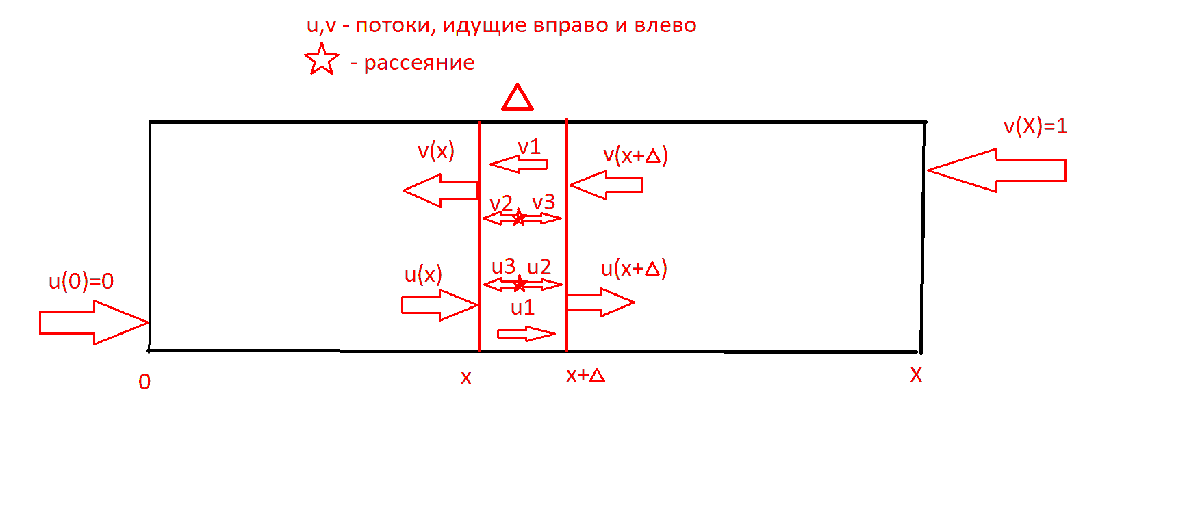

Рассмотрим небольшой участок пути излучения длиной $\Delta$ и, чтобы сформулировать дифференциальное уравнение переноса, рассмотрим потоки излучения на этом участке. Поток излучения в объеме этого элемента формулируется как сумма потоков движущихся  влево и вправо:

Для излучения, движущегося вправо:


$$U(x+\Delta)=U_1 + U_2 + U_3$$


$U_1 = (1-\sigma\Delta)U(x)$ - излучение, которое пролетает через слой не рассеиваясь ($1 - \sigma\Delta$) - вероятность того, что рассеяния не произойдет (единица минус вероятность рассеяния $\sigma\Delta$).

$U_2 =f \sigma\Delta U(x)$  - доля излучения, рассеянного вперед

$U_3 =b \sigma\Delta V(x+\Delta)$ - часть потока, идущего влево, рассеянная назад (для потока, идущего вправо - это попутное направление).


$$U(x+\Delta) - U(x)=\sigma\Delta[(f-1)U(x) + b V(x+\Delta)] + o(\Delta)$$


Аналогично для потока вправо: $V(x) = (1-\sigma \Delta)V(x+\Delta) +f \sigma\Delta V(x+\Delta) + b\sigma\Delta U(x)$


$$V(x+\Delta) - V(x)=\sigma\Delta[ -b U(x) - (f-1)V(x+\Delta)] + o(\Delta)$$


Теперь можно поделить на $\Delta$ и устремить его к нулю, что даст систему дифференциальных уравнений:


$$\begin{cases} \matrix{\frac{dU}{dx} = \sigma [(f-1)U(x) + b V(x)] \cr \frac{dV}{dx} = \sigma[ -b U(x) - (f-1)V(x)]  } \end{cases} $$


Удобно систему переписать в виде одного векторного уравнения: 

$\frac{d}{dx} \vec{Y} = \sigma[ \matrix{ f-1 & b \cr -b & -(f-1)} ]\vec{Y}; \ \ \vec{Y}=  \matrix{U \cr V}$                                        (1)

Граничные условия :

$U(0)=0$  - слева излучение не падает

$V(X)=1$- справа излучение падает

Это краевая задача 

xmesh = linspace(0,1,30);
solinit = bvpinit(xmesh, @guess)

solinit = struct with fields:
    solver: 'bvpinit'
         x: [0 0.0345 0.0690 0.1034 0.1379 0.1724 0.2069 0.2414 0.2759 0.3103 0.3448 0.3793 0.4138 0.4483 0.4828 0.5172 0.5517 0.5862 0.6207 0.6552 0.6897 0.7241 0.7586 0.7931 0.8276 0.8621 0.8966 0.9310 0.9655 1]
         y: [2×30 double]
     yinit: @guess


sigma=1.939

sigma = 1.9390

forward_fraction = 0.767

forward_fraction = 0.7670

alfa = 0

alfa = 0

backward_fraction = 1 - forward_fraction

backward_fraction = 0.2330

dy_fun = dy(sigma,alfa,backward_fraction,forward_fraction)

dy_fun = function_handle with value:
    @(x,y)[sigma*(f-1)-alfa,sigma*b;-sigma*b,-sigma*(f-1)+alfa]*y(:)


sol = bvp4c(dy_fun, @bcfun, solinit)

sol = struct with fields:
    solver: 'bvp4c'
         x: [0 0.0345 0.0690 0.1034 0.1379 0.1724 0.2069 0.2414 0.2759 0.3103 0.3448 0.3793 0.4138 0.4483 0.4828 0.5172 0.5517 0.5862 0.6207 0.6552 0.6897 0.7241 0.7586 0.7931 0.8276 0.8621 0.8966 0.9310 0.9655 1]
         y: [2×30 double]
        yp: [2×30 double]
     stats: [1×1 struct]


t = sol.y(2,1);
r = sol.y(1,end);
a = 1 - t - r

a = 1.1102e-16

%{
plot(sol.x, sol.y,"-o" )
legend(["right", "left"])
title ( "albedo = "+ ...
    string(sigma/(sigma+alfa)) ...
    +"  t= "+string(t)+ ...
    "  r= "+string(r) + ...
    " a = "+string(a))
%}

dR_fun = dRdx(sigma,alfa,backward_fraction,forward_fraction)

dR_fun = function_handle with value:
    @(x,R)sigma*(b+2*((f-1))*R+R.*R*b)-2*alfa*R


F = ode;
F.ODEFcn = dR_fun;
F.InitialValue = 0;
sol_inv = solve(F,0,1)

sol_inv =   ODEResults with properties:

        Time: [0 1.1120e-04 2.2240e-04 3.3359e-04 4.4479e-04 0.0010 0.0016 0.0021 0.0027 0.0054 0.0082 0.0110 0.0138 0.0277 0.0416 0.0555 0.0694 0.0944 0.1194 0.1444 0.1694 0.1944 0.2194 0.2444 0.2694 0.2944 0.3194 0.3444 0.3694 0.3944 … ] (1×57 double)
    Solution: [0 5.0235e-05 1.0047e-04 1.5069e-04 2.0091e-04 4.5194e-04 7.0283e-04 9.5361e-04 0.0012 0.0025 0.0037 0.0049 0.0062 0.0124 0.0184 0.0245 0.0304 0.0409 0.0512 0.0612 0.0711 0.0807 0.0902 0.0994 0.1085 0.1174 0.1261 0.1346 … ] (1×57 double)


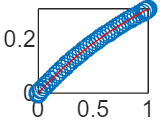


r_dir =  zeros(size(sol_inv.Time));
t_dir =  ones(size(sol_inv.Time));
for i =2:numel(sol_inv.Time)
    [r_dir(i),t_dir(i)] = r_direct(sol_inv.Time(i),alfa,sigma,forward_fraction,backward_fraction);
end
plot(sol_inv.Time,r_dir,'o',sol_inv.Time,sol_inv.Solution,'r')

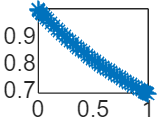

plot(sol_inv.Time,t_dir,'*')

%% задачка
function s = fval(N)
% прямое суммирование 
    a = 3;
    s = sqrt(3);
    for i = 1:N
        s = sqrt(s + a);
    end
end
function s = fval_rec(s,i,N)
% суммирование через рекурсию
    a=3; 
    if i>=N
        return
    else
         s= sqrt(a + fval_rec(s,i+1,N));
    end
end
%% последовательность фибоначчи
function val = fib_dir(N)
% процедурное решение
    if N<=2
        val = 1;
        return
    end
    val = 0;
    x1 = 1;
    x2 = 1;
    for i = 3:N
        val = x1 + x2;
        x1 = x2;
        x2 = val;
    end
end
function val = fib_rec(N)
% рекурсивное решение
    if N<=2
        val = 1;
        return
    end
    val  = fib_rec(N-1) + fib_rec(N-2);
end
function plotFibTreeGraph(n)
    % для построения графа используем рекурсию в процедурном 
    % стиле
    edges = [];
    labels = string([]);
    nodeCount = 0;
    
    % рекурсиный вызов (как в простой версии 
    % рекурсивной функции, только каждый нод добавляется в граф)
    % nested function (переменные edges,labels и nodeCount) для нее
    % глобальные
    function nodeID = buildFibGraph(num)
        nodeCount = nodeCount + 1; 
        nodeID = nodeCount;
        val = fib_mem(num);
        labels(nodeID) = "#"+string(num)+"="+string(val);
        if num <= 2
            return; 
        end
        % рекурсиный вызов
        leftID = buildFibGraph(num - 1);
        rightID = buildFibGraph(num - 2);
        
        edges(end+1, :) = [nodeID, leftID];
        edges(end+1, :) = [nodeID, rightID];
    end

    % запуск расчета
    buildFibGraph(n);
    
    % строим направленный граф 
    G = digraph(edges(:,1), edges(:,2));
    
    % рисуем граф
    figure;
    h = plot(G, 'Layout', 'layered', 'NodeLabel', labels, 'Direction','down', ...
        'Interpreter','none', 'NodeFontSize', 10, 'MarkerSize', 7);
    title(sprintf('Фибоначчи n = %d', n));
    set(gca,'XTick',[], 'YTick', []);
end
%% Решение уравнения переноса в двух-потоковом приближении

function fun = dy(sigma,alfa,b,f)
 % функция оборачивает конкретные значения параметров в анонимную функцию, 
 % которая будет использована в решателе краевых задач 
    B = zeros(2);
    B(1) = sigma*(f-1)-alfa;
    B(2) = sigma*b;
    B(3) = -B(2);
    B(4) = -B(1);
    fun = @(x,y)B*y(:);% первый аргумент  - независимая переменная 
    % второй аргумент - само значение функции
end
function res = bcfun(ya,yb)
res = [ya(1)
       yb(2)-1];
end
function g = guess(x)
    g = [0.5*x 
        x];
end

function [r,t] = r_direct(l,alfa,sigma,f,b)
        dy_fun = dy(sigma,alfa,b,f);
        xmesh = linspace(0,l,10);
        solinit = bvpinit(xmesh, @guess);
        sol = bvp4c(dy_fun, @bcfun, solinit);
        t = sol.y(2,1);
        r = sol.y(1,end);    
end
function fun =dRdx(sigma,alfa,b,f)
    fun = @(x,R) sigma*(b + 2*((f-1))*R  + R.*R*b) - 2*alfa*R;
end

